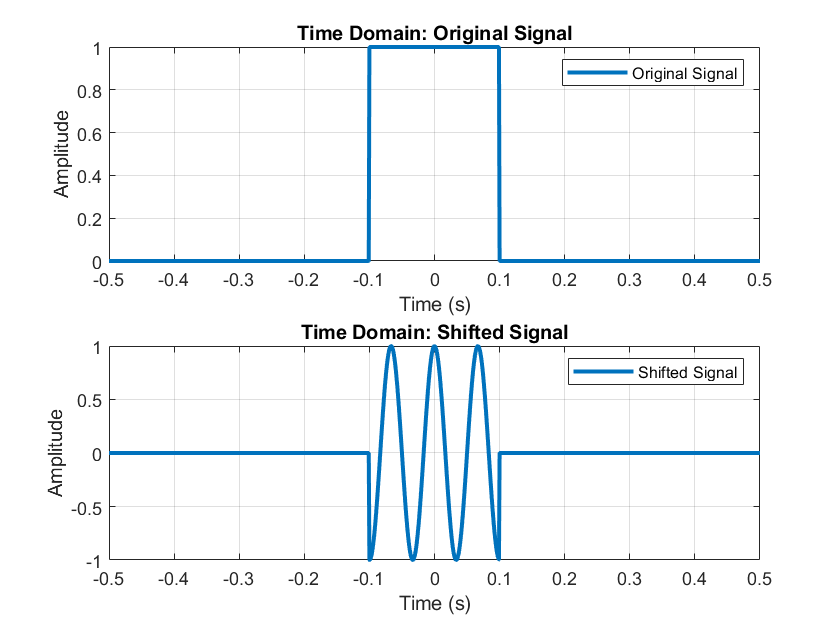

% Parameters
fs = 1000;      % Sampling frequency
T = 1/fs;       % Sampling period
t = -0.5:T:0.5;  % Time vector for a rectangular pulse centered at 0

% Original Rectangular Pulse Signal
f_original = 5; % Frequency of the original signal
x_original = rectpuls(t, 0.2);

% Compute the Fourier Transform of the original signal
X_original = fftshift(fft(x_original));
frequencies = linspace(-fs/2, fs/2, length(X_original));

% Frequency shift by multiplying with a complex exponential
f_shifted = f_original + 10; % Frequency shift by 10 Hz
x_shifted = x_original .* exp(1j*2*pi*f_shifted*t);

% Compute the Fourier Transform of the shifted signal
X_shifted = fftshift(fft(x_shifted));

% Plot the time domain signals
figure;

subplot(2, 1, 1);
plot(t, x_original, 'LineWidth', 2, 'DisplayName', 'Original Signal');
title('Time Domain: Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal');
grid on;

subplot(2, 1, 2);
plot(t, real(x_shifted), 'LineWidth', 2, 'DisplayName', 'Shifted Signal');
title('Time Domain: Shifted Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Shifted Signal');
grid on;

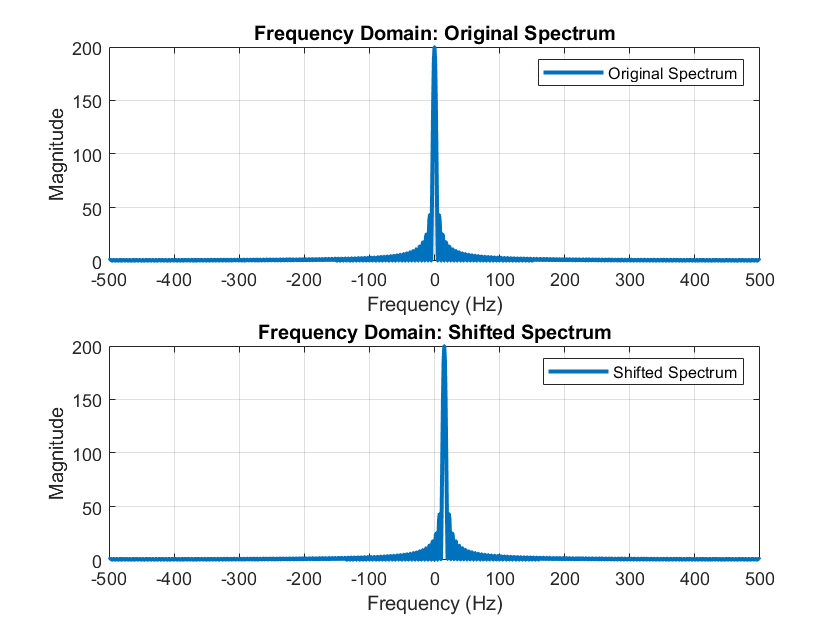


% Plot the magnitudes of the Fourier Transforms
figure;

subplot(2, 1, 1);
plot(frequencies, abs(X_original), 'LineWidth', 2, 'DisplayName', 'Original Spectrum');
title('Frequency Domain: Original Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original Spectrum');
grid on;

subplot(2, 1, 2);
plot(frequencies, abs(X_shifted), 'LineWidth', 2, 'DisplayName', 'Shifted Spectrum');
title('Frequency Domain: Shifted Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Shifted Spectrum');
grid on;